# Algorithm Harris Corner Detector

Jesus Molina Roldan

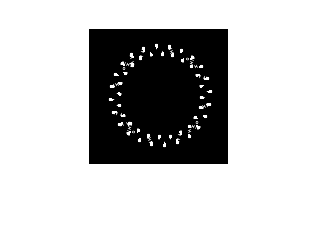

clear
im = imread('gear.tif');
im2 = im;
h = fspecial('Sobel');
gy = imfilter(double(im),h);
gx = imfilter(double(im),h');
h = fspecial('average');
gxx = imfilter(gx.^2,h);
gyy = imfilter(gy.^2,h);
gxy = imfilter(gx.*gy,h);
k = 0.04;
R = gxx.*gyy- ((gxy).^2)-k*((gxx+gyy).^2);
imshow(R);

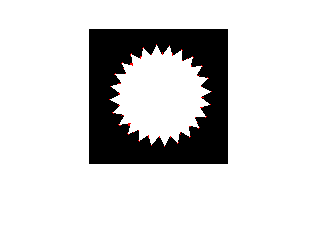

ee = strel('disk',1);
R = imerode(R,ee);
r = double(im2);
r(R > 0) = 255;
im = cat(3,double(r),double(im2),double(im2));
imshow(im)

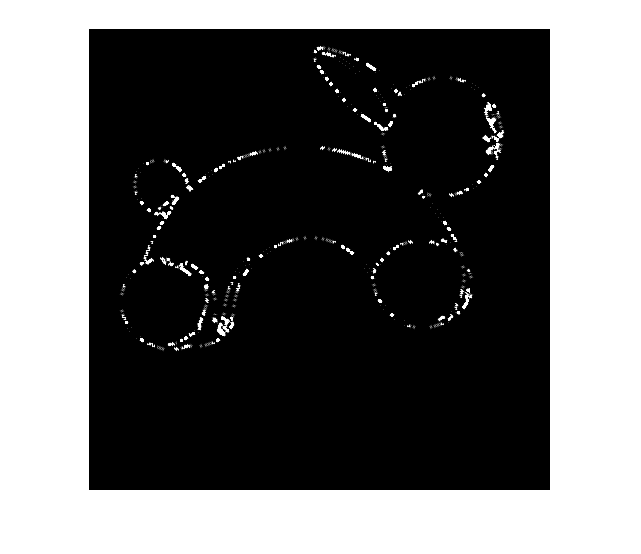



im2 = imread('rabbit.jpg');
im = edge(im2,'canny', [0.1 0.2], 2);
h = fspecial('Sobel');
gy = imfilter(double(im),h);
gx = imfilter(double(im),h');
h = fspecial('average');
gxx = imfilter(gx.^2,h);
gyy = imfilter(gy.^2,h);
gxy = imfilter(gx.*gy,h);
k = 0.04;
R = gxx.*gyy- ((gxy).^2)-k*((gxx+gyy).^2);
imshow(R)

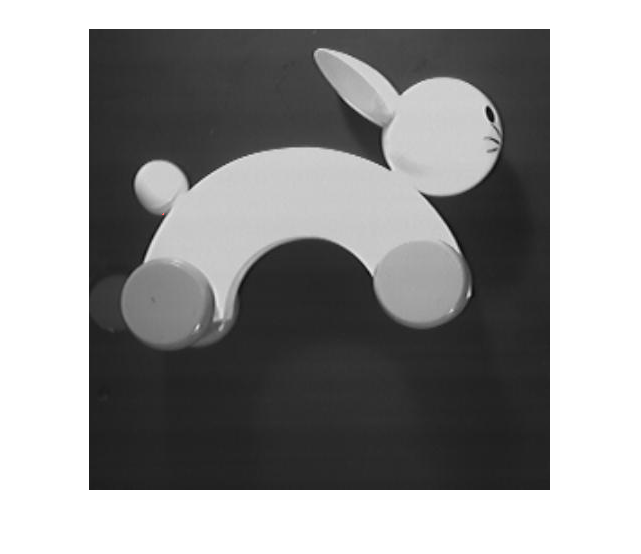

maximos = maxk(R(:),3);
r = im2;
r(R == maximos(1) | R == maximos(2) | R == maximos(3)) = 255;
im = cat(3,r,im2,im2);
imshow(im)